# Operaciones con señales en tiempo continuo

Autor(a): Alejandro Castro Carrera, Universidad de las Fuerzas Armadas - ESPE

## Resumen

*En esta sesión trabajaremos con las operaciones fundamentales aplicadas a señales en tiempo continuo, un conocimiento clave para el análisis y diseño de sistemas en telecomunicaciones. A través de actividades prácticas, discusiones guiadas y el uso de herramientas computacionales como MATLAB, los estudiantes identificarán, aplicarán y analizarán transformaciones como el desplazamiento, escalamiento, inversión y superposición de señales. El propósito es que al finalizar la clase cada estudiante no solo reconozca y comprenda el efecto de estas operaciones, sino que también sea capaz de aplicarlas y justificar sus resultados en contextos prácticos, fortaleciendo así sus competencias para enfrentar problemas reales de ingeniería.*

## Objetivos de Aprendizaje

*Objetivo General:*

* Al finalizar la sesión, los estudiantes serán capaces de identificar, aplicar y analizar operaciones fundamentales con señales en tiempo continuo, demostrando su comprensión mediante ejercicios prácticos y resolución de problemas en un tiempo máximo de 90 minutos.*

*Objetivos Específicos:*

- *Al finalizar la primera parte de la sesión, los estudiantes podrán enumerar y describir al menos 4 operaciones básicas de señales en tiempo continuo (desplazamiento, inversión, escalamiento, superposición) con un 90% de precisión en un cuestionario diagnóstico.*

- *Durante la sesión, los estudiantes podrán explicar con sus propias palabras el efecto de cada operación en una señal de tiempo continuo, presentando ejemplos gráficos en una actividad de 15 minutos.*

- *En un ejercicio práctico de clase, los estudiantes podrán aplicar correctamente al menos 3 operaciones distintas a una señal dada, verificando resultados con MATLAB, con una tasa mínima de éxito del 80%.*

- *Al final de la sesión, los estudiantes serán capaces de comparar y diferenciar los efectos de dos operaciones consecutivas sobre una misma señal, justificando sus resultados en un informe corto de 1 página.*

## Antes de empezar 

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Sección 1: Conceptos 

En el análisis de señales y sistemas, resulta fundamental comprender cómo distintas operaciones transforman una señal en tiempo continuo. Estas operaciones permiten modelar fenómenos físicos, modificar señales para su transmisión o procesamiento, y constituyen la base para estudiar posteriormente sistemas lineales invariantes en el tiempo (LTI).

Sea una señal genérica en tiempo continuo:


$$x\left(t\right)$$


A continuación, se describen las principales operaciones y sus efectos matemáticos y gráficos:

**1. Desplazamiento en el tiempo**

Consiste en adelantar o retrasar una señal:


$$y\left(t\right)=x\left(t-t_0 \right)$$


Si $t_0 >0$, la señal se desplaza hacia la derecha.

Si $t_0 <0$, la señal se desplaza hacia la izquierda.

**2. Escalamiento en el tiempo**

Modifica la duración de la señal:


$$y\left(t\right)=x\left(\mathrm{at}\right);a\not= 0$$


Si $|a|>1$: la señal se comprime en el tiempo.

Si $0<|a|<1$: la señal se expande en el tiempo.

**3. Inversión en el tiempo**

Refleja la señal respecto al eje vertical:


$$y\left(t\right)=x\left(-t\right)$$


**4. Escalamiento en amplitud**

Modifica la magnitud de la señal:


$$y\left(t\right)=A\cdot x\left(t\right),A\in \mathbb{R}$$


Si $|A|>1$: la señal se amplifica.

Si $0<|A|<1$: la señal se atenúa.

**5. Inversión en amplitud**

Refleja la señal respecto al eje horizontal:


$$y\left(t\right)=-x\left(t\right)$$


**6. Superposición (suma de señales)**

La combinación lineal de dos señales produce una nueva señal:


$$y\left(t\right)=x_1 \left(t\right)+x_2 \left(t\right)$$


**Relevancia en Telecomunicaciones**

Estas operaciones permiten modelar retardos de propagación, cambios de frecuencia, inversiones de fase y combinaciones de señales, fenómenos comunes en sistemas de comunicación analógicos y digitales. Dominar estos conceptos constituye la base para comprender temas más avanzados como la convolución, el filtrado y la transformada de Fourier.

% Celda para adicionar código

## Sección 2: Ejercicio 1

Definición de la señal continua en el tiempo.

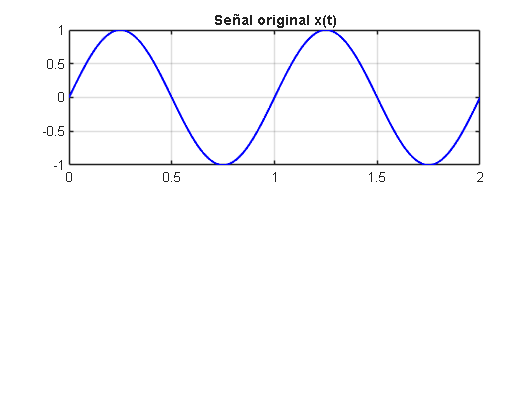

clc,clear,close all;
t = linspace (0,2,1000);
x = sin(2*pi*t);

figure;
subplot(2,1,1);
plot(t,x,'b','LineWidth',1.5);
title('Señal original x(t)'); grid on;



% Celda para adicionar código

## Sección 3: Ejercicio 2

Desplazamiento temporal de la señal x(t).

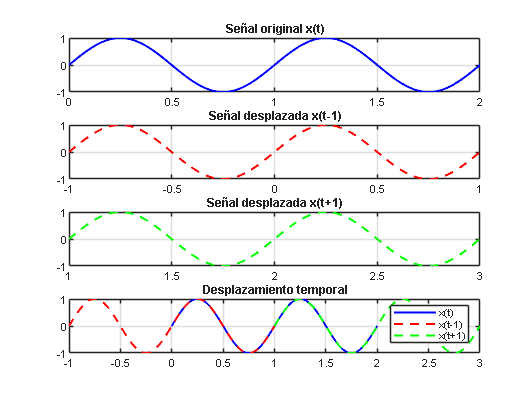

t_shift1 = t-1;
t_shift2 = t+1;

figure;
subplot(4,1,1);
plot(t,x,'b','LineWidth',1.5);
title('Señal original x(t)'); grid on;
subplot(4,1,2);
plot(t_shift1,x,'r--','LineWidth',1.5);
title('Señal desplazada x(t-1)'); grid on;
subplot(4,1,3);
plot(t_shift2,x,'g--','LineWidth',1.5);
title('Señal desplazada x(t+1)'); grid on;
subplot(4,1,4);
plot(t,x,'b',t_shift1,x,'r--',t_shift2,x,'g--','LineWidth',1.5);
title('Desplazamiento temporal'); grid on;
legend('x(t)','x(t-1)','x(t+1)');




% Celda para adicionar código


## Sección 4: Ejercicio 3

Escalamiento en amplitud.

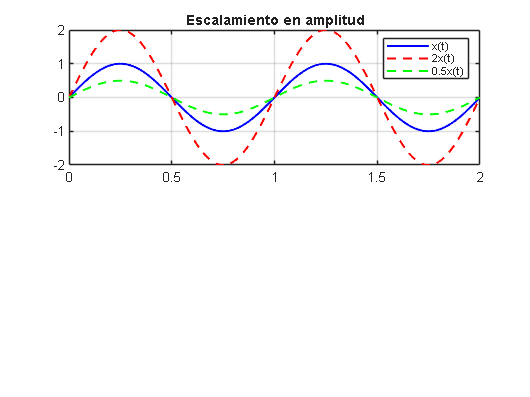

x2 = 2*x;
x05 = 0.5*x;

figure;
subplot(2,1,1);
plot(t,x,'b',t,x2,'r--',t,x05,'g--','LineWidth',1.5);
legend('x(t)','2x(t)','0.5x(t)');
title('Escalamiento en amplitud'); grid on;

## Sección 5: Ejercicio 4

Escalamiento en el tiempo.

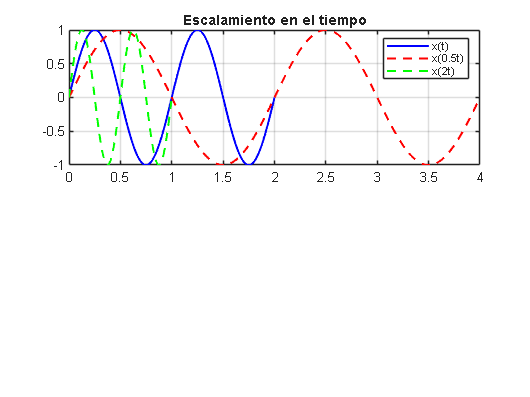

t2short = 2*t;
t05large = 0.5*t;

figure;
subplot(2,1,1);
plot(t,x,'b',t2short,x,'r--',t05large,x,'g--','LineWidth',1.5);
legend('x(t)','x(0.5t)','x(2t)');
title('Escalamiento en el tiempo'); grid on;

## Sección 6: Ejercicio 5

Inversión en el tiempo.

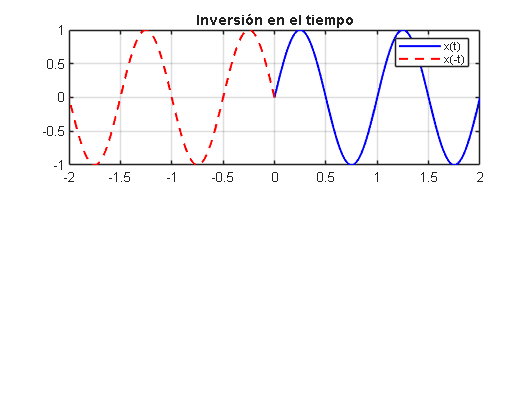

tneg = -t;

figure;
subplot(2,1,1);
plot(t,x,'b',tneg,x,'r--','LineWidth',1.5);
legend('x(t)','x(-t)');
title('Inversión en el tiempo'); grid on;

## Sección 7: Ejercicio 6

Inversión en el amplitud.

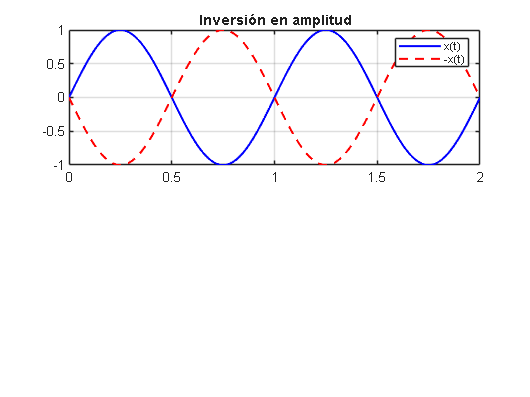

xneg = -x;

figure;
subplot(2,1,1);
plot(t,x,'b',t,xneg,'r--','LineWidth',1.5);
legend('x(t)','-x(t)');
title('Inversión en amplitud'); grid on;

## Sección 8: Ejercicio 7

Superposición.

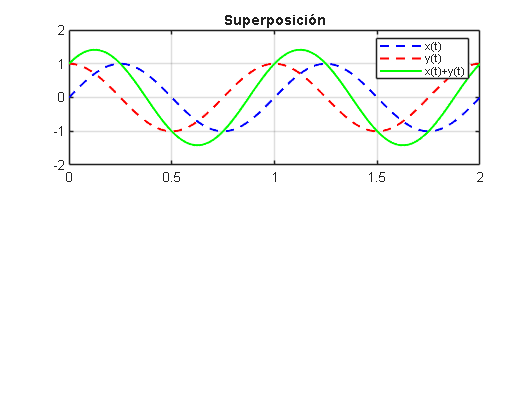

y = cos(2*pi*t);
s = x+y;

figure;
subplot(2,1,1);
plot(t,x,'b--',t,y,'r--',t,s,'g','LineWidth',1.5);
legend('x(t)','y(t)','x(t)+y(t)');
title('Superposición'); grid on;

## Recursos Adicionales

En esta sección comparta enlaces o referencias adicionales para los educadores y estudiantes que usen este material

## Referencias 

Oppenheim, Alan V. & Willsky, Alan (1997) Signals and systems

Hsu P. Hwei (1995), Schaum's Outline of Signals and Systems